clear workspace;
filename="meas5.wav";
SDR=audioread(filename);
info = audioinfo(filename)

info = struct with fields:
             Filename: 'C:\Users\Wout\OneDrive - Universiteit Antwerpen\Documenten\Master\1 MAP\Simulation\SNR\Precise SNR FFT\meas5.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 2
           SampleRate: 1000000
         TotalSamples: 136860000
             Duration: 136.8600
                Title: '137.55 MHz, BW 1 MHz, 2023-02-23 12:58'
              Comment: 'Created by DESKTOP-3EC4Q02\Wout on 2023-02-23 12:58:36, filename C:\Users\Wout\OneDrive - Universiteit Antwerpen\Bureaublad\23-Feb-2023 125836.937 137.550MHz.wav'
               Artist: 'SDR-Radio.com, B210 (A:A)'
        BitsPerSample: 32


sampleRate= info.SampleRate;
RecordingTime=info.TotalSamples/sampleRate;
center_freq=137.55E6; %in MHz

IQData = SDR(:,1)+1i*SDR(:,2); %Get the IQ data from the columns and put them togheter as a complex value



for i=0:1:floor(RecordingTime-1)
    if i==0
        [fft_power, fft_dBm] = Precise_FFT(IQData,1,1*sampleRate,sampleRate,center_freq);
        [noise_level_dBm(i+1),signal_level_dBm(i+1),snr(i+1), CN0(i+1)] = SNR_V2(fft_power,sampleRate,center_freq,center_freq+57300,center_freq+160000);
    else
        [fft_power, fft_dBm] = Precise_FFT(IQData,i*sampleRate,1*sampleRate,sampleRate,center_freq);
        [noise_level_dBm(i+1),signal_level_dBm(i+1),snr(i+1), CN0(i+1)] = SNR_V2(fft_power,sampleRate,center_freq,center_freq+57300,center_freq+160000);
    end
    
end

The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


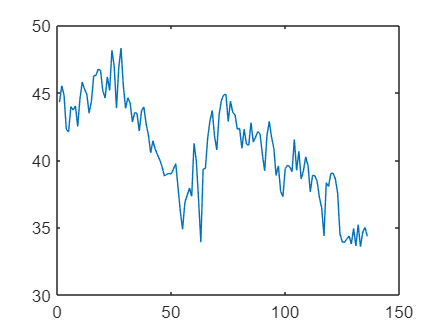

CN0=CN0;
time=linspace(1,length(CN0),length(CN0));
plot(time,CN0)